## load files

close all
clear

% SF_T_string_05Hz_6kV_Rampedsquare_25kVs_2022_10_25_1312
% 123456789012345678901234567890123456789012345678901234567890
% 0        1         2         3         4         5         6

% FName = dir('SF_T_string_05Hz_6kV_*.txt') % comparison [step vs ramp] in T-string
% FName = dir('SF_Y_string_05Hz_6kV_*.txt') % comparison [step vs ramp] in Y-string
% FName = dir('SF_*_string_05Hz_6kV_Ramp*.txt') % comparison [string type] in ramp
% FName = dir('SF_*_string_05Hz_6kV_Step*.txt') % comparison [string type] in step
FName = dir('Fm40_ns_21nc_4_r3.txt') % Johannes data

FName = struct with fields:
       name: 'Fm40_ns_21nc_4_r3.txt'
     folder: '\\space\fukushima\251022\toshi'
       date: '04-Nov-2022 14:55:46'
      bytes: 775
      isdir: 0
    datenum: 7.3883e+05


## etc.

% FName(1).name = '10x90_new_05Hz_7kV_Rampedsquare_25kVs_2022_05_11_1140.txt';
% FName(2).name = '10x90_old_05Hz_7kV_Rampedsquare_25kVs_2022_05_11_1202.txt';
% FName(3).name = '20x60_new_05Hz_7kV_Rampedsquare_25kVs_2022_05_11_1245.txt';
% FName(4).name = '20x60_old_05Hz_7kV_Rampedsquare_25kVs_2022_05_11_1223.txt';

% FName(1).name = '10x60_EUP_FR3_00_05Hz_7kV_Rampedsquare_25kVs.txt';
% FName(2).name = '20x60_EUP_FR3_00_05Hz_7kV_Rampedsquare_25kVs.txt';
% FName(3).name = '10x60_EUP_FR3_85_05Hz_7kV_Rampedsquare_25kVs.txt';
% FName(4).name = '20x60_EUP_FR3_85_05Hz_7kV_Rampedsquare_25kVs.txt';

% FName(1)s.name = '20x60_EUP_FR3_00_05Hz_7kV_Stepinput.txt';
% FName(2).name = '20x60_EUP_FRB_00_05Hz_10kV_Stepinput.txt';
% FName(1).name = '20x60_EUP_FR3_00_05Hz_7kV_Rampedsquare_25kVs.txt';
% FName(2).name = '20x60_EUP_FRB_00_05Hz_10kV_Rampedsquare_36kVs.txt';


## experimental parameters

exPara.sampleFreq = 1000;
exPara.forceStep = 2; %N
exPara.forceMax = 40; %N
exPara.voltMax = 6; %kV
exPara.inputFreq = 0.5;
exPara.inputRepeat = 4;
exPara.kF = 9.96; %N/V
exPara.kD = 1.93; %mm/V
exPara.rampTime_step = 0; %kV/s for step input
exPara.rampTime_ramp = 6/25; %kV/(kV/s) for ramp input
% exPara.holdTime = 1/3; % 1/3 of the cycle: hold off ->  ramp up -> hold on -> ramp down -> off till cycle end
exPara.holdTime = 1/2; % 1/3 of the cycle: hold off ->  ramp up -> hold on -> ramp down -> off till cycle end Johannes

## HASEL parameters

HaPara.width_pouch = 60e-3;
HaPara.height_pouch = 20e-3;
HaPara.number_pouch = 7;
HaPara.epsilon_film = 3.2; %Dielectric constant of film / Mylar 3.2, BOPP 2.8
HaPara.epsilon_0 = 8.85 *10^-12;
HaPara.thickness_film = 15*10^-6; %um / Mylar 15um, BOPP 20um

## force-strain plot with saved data

%
% figure(1)
% clf
% legendText = {length(FName), 1};
%
% for i = 1: length(FName)
%     fName = FName(i).name
%     %     [Time, Volt, Force, Disp, Trigger] = importfile_strainRaw(['raw_', fName]);
%     [SF_strain, SF_force] = importfile_strain(fName);
%     %     Volt = correctTimedelay(Volt);
%
%     hold on
%     plot(SF_strain, SF_force, '.-')
%     grid on
%     xlabel('strain [mm]')
%     ylabel('force [N]')
%
%
%     legendText{i} = [fName(1:5), ' ', fName(11:13), ' ', fName(7:9), ' ', fName(15:16), '% air'];
%
% end
%
% legend(legendText)
%


## raw data plot

fName = 'Fm40_ns_21nc_4_r3.txt'

ramping method is not specified


end at38N


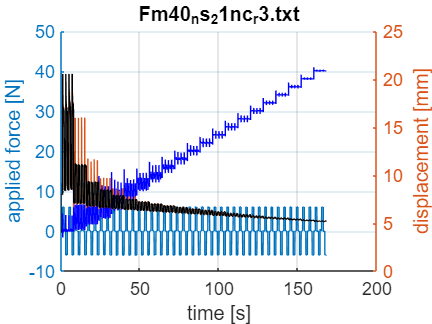

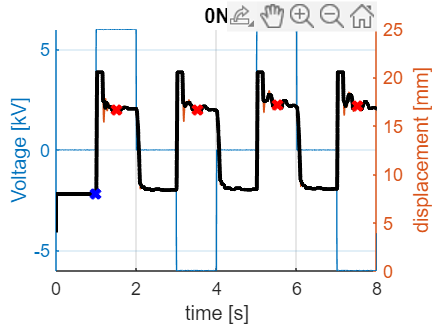

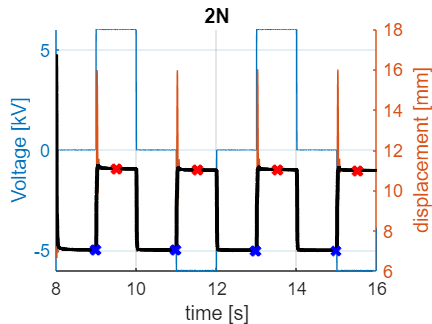

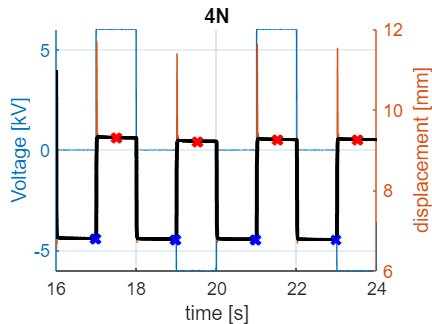

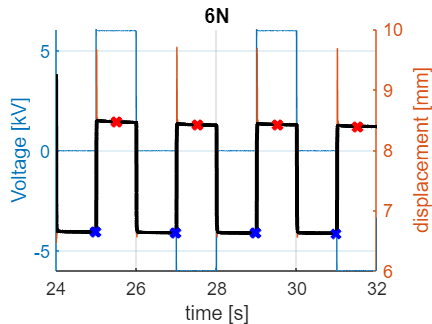

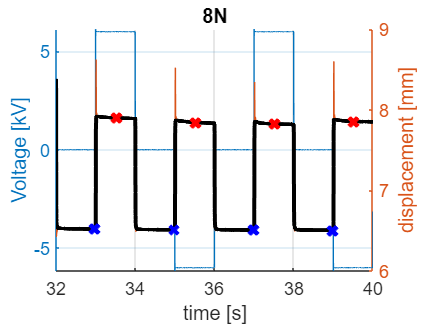

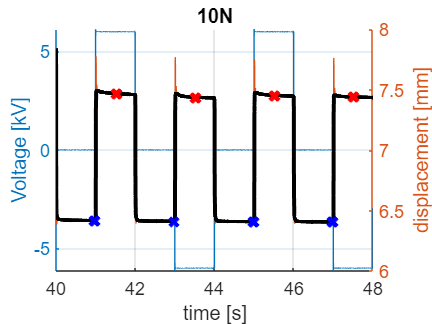

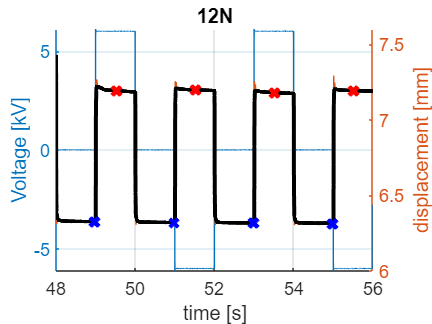

end at38N



TargetForce = [0: 2: 40];


smoothingFactor = exPara.sampleFreq/10;
numForceSteps = exPara.forceMax/exPara.forceStep + 1;

Data(1: length(FName), 1: numForceSteps) =...
    struct('strain_raw', zeros(exPara.inputRepeat, 1), 'strain', 0, 'force', 0);
for i = 1: length(FName)
    %     keyboard
    fName = FName(i).name
    %     if strcmp(fName, '20x60_EUP_SIL_85_05Hz_7kV_Stepinput.txt')
    %         continue
    %     end
    if contains(fName, 'Step')
        exPara.rampTime = exPara.rampTime_step;
    elseif contains(fName, 'Ramp')
        exPara.rampTime = exPara.rampTime_ramp;
    else
        exPara.rampTime = exPara.rampTime_step;
        disp('ramping method is not specified')
    end
%     [Time, Volt, Force, Disp, Trigger] = importfile_strainRaw(['raw_', fName]);
    [Time, Volt, Force, Disp] = importfile_strainRaw_Johannes(['raw_', fName]); % Johannes
    %     [SF_strain, SF_force] = importfile_strain(fName);
    %     Disp = -Disp*exPara.kD;
    Disp = -Disp;
    Force = Force;
    Volt = correctTimedelay(Volt);
    
    % filter raw data
    Disp_fil = medfilt1(Disp, smoothingFactor);
    Force_fil = medfilt1(Force, smoothingFactor);
    
    % plot overall
    figure(100*i)
    clf
    hold on
    
    yyaxis('left')
    plot(Time, Volt)
    plot(Time, Force, 'b-')
    ylabel('applied force [N]')
    xlabel('time [s]')
    
    yyaxis('right')
    plot(Time, Disp)
    plot(Time, Disp_fil, 'k-')
    %     ylim([-0.5, 1.5])
    ylabel('displacement [mm]')
    grid on
    
    
    % calculate strain
    
    
    for j = 1: numForceSteps
        if length(Time) <= j * exPara.sampleFreq * exPara.inputRepeat / exPara.inputFreq
            disp(['end at', num2str((j-1-1)*exPara.forceStep), 'N'])
            break
        end
        Data(i, j) = detectStrain_cnv(Time, Force_fil, Disp_fil, (j-1)*exPara.forceStep, exPara, 0);
    end
    
    
    
%     title([fName(4:4), ' ', fName(18:20), ' ', fName(22:25)])
    title(fName) % Johaness
    for j = 1: numel(TargetForce)
        targetForce = TargetForce(j);
        idx0 = fix(targetForce/exPara.forceStep*1/exPara.inputFreq*exPara.inputRepeat*exPara.sampleFreq) + 1;
        idx1 = idx0 - 1 + fix(1/exPara.inputFreq*exPara.inputRepeat*exPara.sampleFreq);
        
        if length(Time) <= idx1
            disp(['end at', num2str(TargetForce(j-1)), 'N'])
            break
        end

        figure(100*i+j)
        clf
        hold on
        
        yyaxis('left')
        plot(Time(idx0:idx1), Volt(idx0:idx1))
        %     plot(Time, RefFreq)
        ylabel('Voltage [kV]')
        xlabel('time [s]')
        %     legend('real input', 'ref input for TF', 'output', "Location", "northoutside", "Orientation","horizontal")
        
        yyaxis('right')
        plot(Time(idx0:idx1), Disp(idx0:idx1))
        plot(Time(idx0:idx1), Disp_fil(idx0:idx1), 'k-', 'LineWidth', 2)
        
        %         ylim([-1.0, 1.0])
        ylabel('displacement [mm]')
        grid on
        %         xlim([Time(idx0) - 5/targetFreq, Time(idx0) + 5/targetFreq])
        grid on
        title([num2str(targetForce), 'N'])
        
        detectStrain_cnv(Time, Force_fil, Disp_fil, targetForce, exPara, 1);
        
    end
    
    
end

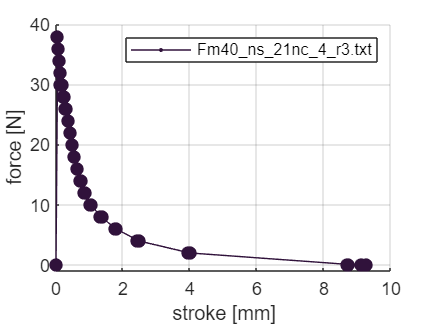

figure(2)
clf
figure(3)
clf
legendText = {};

for i = 1: length(FName)
    fName = FName(i).name;
%     legendText{i} = [fName(4:4), ' ', fName(18:20), ' ', fName(22:25)];
    legendText{i} = fName; % Johaness
    Colors = turbo(length(FName)+1);
    
%     height_pouch = str2num(fName(4:5))*10^-3;
%     width_pouch = str2num(fName(7:8))*10^-3;
%     epsilon_film = 3.2; %Dielectric constant of film / Mylar 3.2, BOPP 2.8
%     epsilon_0 = 8.85 *10^-12;
%     thickness_film = 15*10^-6; %um / Mylar 15um, BOPP 20um
    
    nom = HaPara.width_pouch/(4*HaPara.thickness_film)*(HaPara.epsilon_0*HaPara.epsilon_film*(exPara.voltMax*10^3)^2);
    
    
    figure(2) % force - strain plot
    hold on
    h2(i) = plot([Data(i, :).strain], [Data(i, :).force], '.-', 'Color', Colors(i, :));
    plot([Data(i, :).strain_raw], repmat([Data(i, :).force], exPara.inputRepeat, 1), '.', "MarkerEdgeColor", Colors(i, :), 'MarkerSize', 20)
    grid on
    xlabel('stroke [mm]')
    ylabel('force [N]')
    legend(h2, legendText, "Interpreter", "none")
    tmp = get(gca, 'YLim');
    tmp(1) = -1;
    ylim(tmp);
    
    figure(3) % force - strain plot with normalization
    hold on
    h3(i) = plot([Data(i, :).strain]/(HaPara.height_pouch*1e3*HaPara.number_pouch)*100, [Data(i, :).force]/nom, '.-', 'Color', Colors(i, :));
    plot([Data(i, :).strain_raw]/(HaPara.height_pouch*1e3*HaPara.number_pouch)*100, repmat([Data(i, :).force]/nom, 4, 1), '.', "MarkerEdgeColor", Colors(i, :), 'MarkerSize', 20)
    grid on
    xlabel('strain [%]')
    ylabel('normalized force [-]')
    legend(h3, legendText, "Interpreter", "none")
    tmp = get(gca, 'YLim');
    tmp(1) = -1;
    ylim(tmp);
end

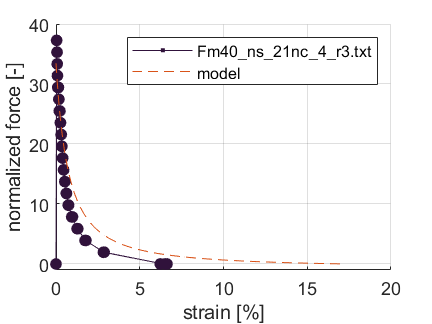


modelPlot

## plot bode with a new calculation

you can test other parameters for tfestimate


% figure(3)
% sampleRate = 2000;
% wind = hamming(sampleRate*2);
% [txy, ft] = tfestimate(refVolt, length, wind, [], [], sampleRate);
%
% subplot(2,1,1)
% hold on
% plot(ft, 10*log(abs(txy)))
% grid on
% xlim([0, 100])
%
% subplot(2,1,2)
% hold on
% plot(ft, unwrap(angle(txy))*180/pi)
% xlim([0, 100])
% grid on

function Out = correctTimedelay(Data)
Out = [Data(2:end); Data(end)];
end

function Out = detectStrain(Time, Force, Disp, targetForce, exPara, flagPlot)
samplesPerVolt = exPara.sampleFreq/exPara.inputFreq; % num samples per volt
samplesPerForceStep = samplesPerVolt * exPara.inputRepeat; % num samples per displacement step


i = targetForce/exPara.forceStep + 1;
startIndex = (i - 1)*samplesPerForceStep + 1;
endIndex = i*samplesPerForceStep;

Out.force = -mean(Force(startIndex: endIndex));

Ind_max = zeros(exPara.inputRepeat, 1);
Ind_min = zeros(exPara.inputRepeat, 1);
Val_max = zeros(exPara.inputRepeat, 1);
Val_min = zeros(exPara.inputRepeat, 1);

for j = 1: exPara.inputRepeat
    startIndex2 = startIndex + (j - 1)*samplesPerVolt;
    midIndex2 = startIndex2 + (1/2)*samplesPerVolt;
    endIndex2 = (startIndex - 1) + j*samplesPerVolt;
    [Val_max(j), Ind_max(j)] = max(Disp(startIndex2: midIndex2));
    [Val_min(j), Ind_min(j)] = min(Disp(midIndex2: endIndex2));
    
    Ind_max(j) = Ind_max(j) + startIndex2 - 1;
    Ind_min(j) = Ind_min(j) + midIndex2 - 1;
    
    if flagPlot
        yyaxis('right')
        plot(Time(Ind_min(j)), Disp(Ind_min(j)), 'bo', "LineWidth", 2)
        plot(Time(Ind_max(j)), Disp(Ind_max(j)), 'ro', 'LineWidth', 2)
    end
end
Out.strain_raw = Val_max - Val_min;
Out.strain = mean(Out.Strain_raw);

end


function out = detectStrain_cnv(Time, Force, Disp, targetForce, exPara, flagPlot)

spc= exPara.sampleFreq/exPara.inputFreq;
spf = spc * exPara.inputRepeat; % num samples per displacement step

i = targetForce/exPara.forceStep + 1;
startIndex = (i - 1)*spf + 1;
% endIndex = i*samplesPerForceStep;

max_stroke = zeros(exPara.inputRepeat, 1);
min_stroke = zeros(exPara.inputRepeat, 1);
rawStroke = zeros(exPara.inputRepeat, 1);
force = zeros(exPara.inputRepeat, 1);

rdr = exPara.rampTime*exPara.inputFreq; % ramp delay ratio in a cycle
hold = exPara.holdTime;

for j = 1: exPara.inputRepeat
    if i == 1
        ind_min_start = fix(startIndex + (hold - 0.01)*spc);
        ind_min_end = fix(startIndex + (hold + 0.00)*spc);
    else
        ind_min_start = fix(startIndex + (hold - 0.01)*spc +spc*(j-1));
        ind_min_end = fix(startIndex + (hold + 0.00)*spc +spc*(j-1));
    end
    ind_max_start = fix(startIndex + (hold + rdr + hold/2 + 0.01)*spc +spc*(j-1));
    ind_max_end = fix(startIndex + (hold + rdr + hold/2 + 0.02)*spc +spc*(j-1));
    
    max_stroke(j)=mean(Disp(ind_max_start: ind_max_end));
    min_stroke(j)=mean(Disp(ind_min_start: ind_min_end));
    force(j) = -mean(Force(ind_min_start: ind_min_end));
    
    rawStroke(j)= max([0, max_stroke(j) - min_stroke(j)]);
    
    if flagPlot
        yyaxis('right')
        plot([Time(ind_min_start), Time(ind_min_end)], [min_stroke(j), min_stroke(j)], 'bx-', "LineWidth", 2)
        plot([Time(ind_max_start), Time(ind_max_end)], [max_stroke(j), max_stroke(j)], 'rx-', "LineWidth", 2)
    end
end
out.strain_raw = rawStroke;
out.strain = mean(rawStroke);
out.force = targetForce;
% out.force = mean(force);


end

function modelPlot()
alpha0=0.2415; %alpha0 is constant with optimal filling
Alpha = linspace(alpha0,pi/2-0.01,100);

Force = cos(Alpha)./(1-cos(Alpha));
A = (alpha0 - sin(alpha0)*cos(alpha0))/alpha0^2;
Strain = 1 - alpha0/sin(alpha0).*(1+sqrt(A).*(sin(Alpha) - Alpha)./(sqrt(Alpha - sin(Alpha).*cos(Alpha))));


plot(Strain*100, Force, '--', "DisplayName", 'model')

end